% 2稿目アンケート回答のグラフ化用スクリプト
clear, clc, close all
list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,2);% インポート用のセル

for i = 1:numFiles
    Mx{i,1} = readtable(list(i).name,'PreserveVariableNames',true);
end


for subj = 1:size(Mx{1,1},1)
    % 実験１のアンケート結果を集計
    for i = 3:14
        % 回答を取得
        str = table2array(Mx{1,1}(subj,i));
        %（奇数＝headphone、偶数＝Hapbeat）
        col = 2 - rem(i,2);
        %         1,2 = 1, 3,4=2, 5,6 = 3
        row = ceil ( (i-2) / 2 );
        % 回答文中の数値から回答値を配列に格納
        for k = 0:6
            if contains(str,num2str(k))
                Mx{subj,2}(row, col) = k;
            end
        end
    end
    
    % 実験１.1のアンケート結果を集計
    i = 15; str = table2array(Mx{1,1}(subj,i));
    if contains(str,"was bothering")
        Mx{subj,3} = 2;
    elseif contains(str,"was not bothering")
        Mx{subj,3} = 1;
    elseif contains(str,"could not")
        Mx{subj,3}  = 0;
    end
    
    % 実験2 のアンケート結果を集計
    i = 16; str = table2array(Mx{1,1}(subj,i));
    for k = 0:6
        if contains(str,num2str(k))
            Mx{subj,4} = k;
        end
    end
    
    % 実験３ のアンケート結果を集計
    for i = 17:28

回答を取得

        str = table2array(Mx{1,1}(subj,i));
        %（奇数＝headphone、偶数＝Hapbeat）
        col = 1 + rem(i-1,4);
        % 1,2,3,4 = 1, 3,4=2, 5,6 = 3
        row = ceil ( (i-16) / 4 );
        % 回答文中の数値から回答値を配列に格納
        for k = 0:6
            if contains(str,num2str(k))
                Mx{subj,5}(row, col) = k;
            end
        end
    end
end

arr = ["生データ" "exp1" ...
    "noise" "exp2" "exp3"
    ];
length = arr.length;
% 行末に説明を追加
for k = 1: length
    Mx{size(Mx{1,1},1)+1,k} =arr(1,k);
end

save;


保存先:C:\Dropbox\論文\2稿目_音楽振動ナビ\V2実験データ\exp1--3_qustionnaire\matlab.mat



## 実験１グラフ描画

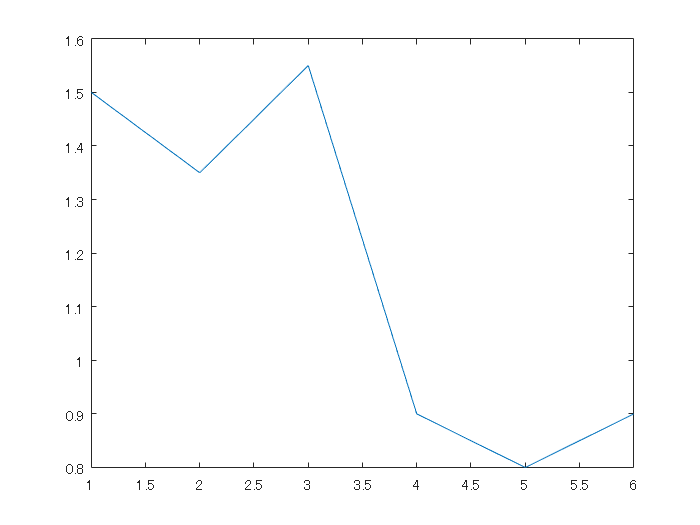

figure;

exp1_mean = zeros(6,2); % 評点の平均値を計算
exp1_std = zeros(6,2); % 評点の標準偏差
exp1_diffmean = zeros(6,1); % hapbeat-headphone
exp1_diffstd = zeros(6,1); % hapbeat-headphone

tmp = zeros(size(Mx,1)-1,2);

for q = 1: 6 %設問数だけイテレート
    for subj = 1: size(Mx,1)-1
        %     平均を取るためtmpに格納
        tmp(subj,1) = Mx{subj,2}(q,1);
        tmp(subj,2) = Mx{subj,2}(q,2);
    end
    %  col 1,2：music mean, std：col3,4:Hapbeat mean, std
    exp1_mean(q,1) = mean(tmp(:,1));
    exp1_mean(q,2) = mean(tmp(:,2));
    exp1_std(q,1) = std(tmp(:,1));
    exp1_std(q,2) = std(tmp(:,2));
    % 
    exp1_diffmean(q,1) = mean(tmp(:,2)-tmp(:,1));
    exp1_diffstd(q,1) = std(tmp(:,2)-tmp(:,1));
end


% hapbeat-headphone で計算した結果を prot で出す。
figure
scatter(exp1_diffmean);


load carsmall
boxplot(tmp(:,1))




## グループ化された棒グラフにエラーバーを付ける

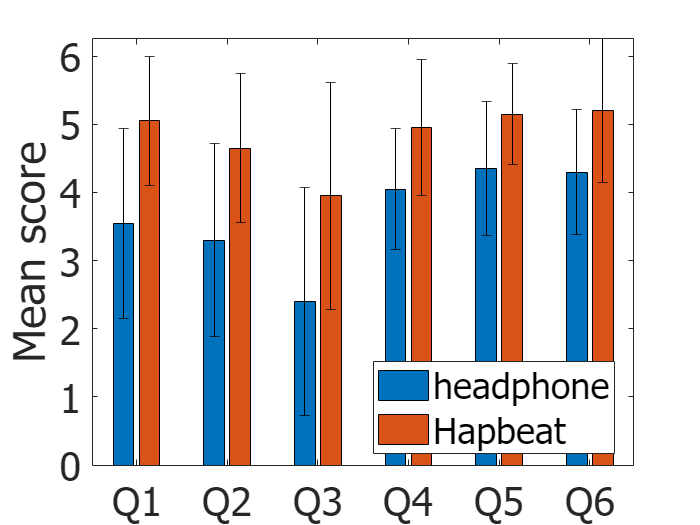

b = bar(exp1_mean, 'grouped');
hold on
[ngroups,nbars] = size(exp1_mean);

% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:nbars
    x(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',exp1_mean,exp1_std,'k','linestyle','none');

xticklabels({'Q1', 'Q2', 'Q3', 'Q4', 'Q5', 'Q6'});
yticklabels([0:6]);
ylabel('Mean score');
legend('headphone', 'Hapbeat');
ax = gca; % current axes
ax.FontSize = 24;
ax.FontName = 'tahoma';
hold off

legend("Position",[0.53452,0.13484,0.34464,0.17738])

## 実験３グラフ描画

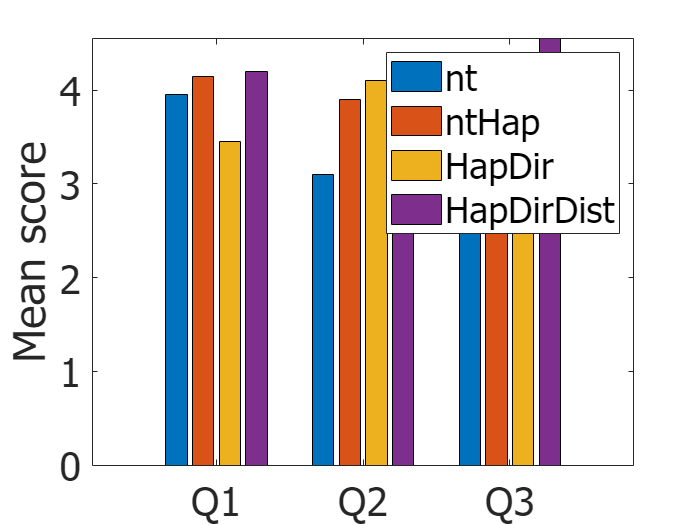

figure;

exp3_mean = zeros(3,4);
exp3_std = zeros(3,4);
tmp = zeros(size(Mx,1)-1,2);
exp3col = 5; % 実験３の回答が格納されたセル列

for q = 1: 3 %設問数だけイテレート
    for subj = 1: size(Mx,1)-1
        %     平均を取るためtmpに格納
        for cond = 1:4
            tmp(subj,cond) = Mx{subj, exp3col}(q,cond);
        end
    end
    
    for cond = 1:4
        exp3_mean(q,cond) = mean(tmp(:,cond));
        exp3_std(q,cond) = std(tmp(:,cond));
    end
end

x = categorical({'Q1', 'Q2', 'Q3'});
bar(x, exp3_mean)
% 最低限、縦軸、横軸、タイトル、凡例は必要。
ylabel('Mean score');
legend('nt', 'ntHap', 'HapDir', 'HapDirDist');
ax = gca; % current axes
ax.FontSize = 24;
ax.FontName = 'tahoma';